# Herbeeb and Brian

%load data
load rowscan.mat
load diag1scan.mat
load diag2scan.mat
load std.mat

%row a, extract travel time
t_row = rowscan(1:16,5);
%diagonal_c, extract travel time
t_diag1 = diag1scan(1:31,5);
%diagonal_d, extract travel time
t_diag2 = diag2scan(1:31,5);

t = [t_row; t_diag1; t_diag2];


%model 
G1 = zeros(16,256);

%row scan 
%parameter indices increase by 17 each column and by 1 each row 
for i = 1:16
    for j = 0:15
       if i+j*16 <= 256
            G1(i,i+j*16) = 1;
       else
           break
       end
    end
end 
G1;

%diagonal scans
%upper part of the SW to NE 
G2 = zeros(16,256);
for i = 1:16
    for j = 0:i-1
        if i+j*15 <= 256
            G2(i,i+j*15) = sqrt(2);
        else
            break
        end       
    end
end

%lower part of the SW to NE
G3 = zeros(15,256);
for i = 1:15
    for j = 0:i-1
        if 256-(i-1)*16+j*15 <= 256

             G3(i, 256-(i-1)*16+j*15) = sqrt(2);
        else
            break
        end
    end
end

G3_new = flipud(G3);

%lowerpart of the NW to SE
G4 = zeros(16,256);
for i = 1:16
    for j = 0:i-1
        if (16-(i-1)+j*17 <= 256)
            G4(i,16-(i-1)+j*17) = sqrt(2);
        else
            break
        end
    end
end


%upper part  of the NW to SE
G5 = zeros(15,256);

for i = 1:15
    for j = 0:i-1
        if (241-(i-1)*16+j*17 <=256)
            G5(i,241-(i-1)*16+j*17) = sqrt(2);
        else
            break
        end
   
    end
end

G5_new = flipud(G5);

G = [G1; G2; G3_new; G4; G5_new];

[m,n] = size(G); % size of G

find(G(78,:)==sqrt(2)); % checking the model matrix

### 4.(a) Note the rank of your G matrix that relates the data and model.

%rank of G
p = rank(G)

p = 74

% %Using SVD
[U,S,V] = svd(G);

Gdagger = V(:,1:p)*inv(S(1:p,1:p))*U(:,1:p)';

mdagger = Gdagger*t;


### 4.b) i. State and discuss significance of the elements and dimensions of the data and model null spaces.

% data null space
data_null_space = U(:,p+1:m)

data_null_space =    -0.0109   -0.3172         0         0
   -0.0274   -0.2920   -0.0033    0.0112
   -0.0438   -0.2668   -0.0066    0.0224
   -0.0602   -0.2416   -0.0099    0.0337
   -0.0767   -0.2164   -0.0132    0.0449
   -0.0931   -0.1912   -0.0165    0.0561
   -0.1095   -0.1660   -0.0198    0.0673
   -0.1260   -0.1408   -0.0231    0.0785
   -0.1424   -0.1156   -0.0264    0.0897
   -0.1588   -0.0904   -0.0296    0.1010


%dimension of the data null spaces
dim_data_null_space = m-p

dim_data_null_space = 4

% model null space
V(:,p+1:n)

ans =    -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0603    0.1240   -0.0442   -0.0446    0.0517    0.0294    0.1198   -0.1210    0.0195    0.0240    0.0259    0.0236   -0.0339   -0.0031   -0.0014    0.0003   -0.0348   -0.0236    0.0041    0.0069    0.0459    0.0511    0.1060   -0.1121   -0.0119    0.0114    0.0403    0.0127    0.0017   -0.0326   -0.0030   -0.0249   -0.0349    0.0163   -0.0100    0.0168    0.0313    0.0258    0.1478   -0.1171   -0.0100   -0.0113    0.0103    0.0131    0.0200    0.0007   -0.0561   -0.0197    0.0111   

%dimension of the model null spaces
dim_model_null_space = n-p

dim_model_null_space = 182

### Discuss the significance of the elements in each null space

Since the model and data null spaces contain non-zero vectors, then the problem under consideration is rank deficient. So, we will have infinitely many models that can fit the data exactly due to the existence of non-trivial model model null space. Also, we have infinitely many data lying in the data null space, this means there are many datasets that can produce the same model parameters.

### Plot and interpret at least one element of each space,

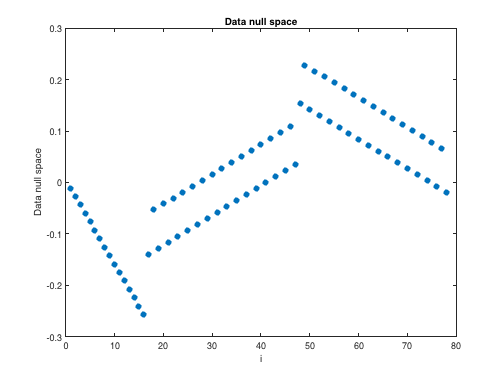

figure(1)
plot(U(:,p+1),'.','MarkerSize',20)
xlabel('i'); ylabel('Data null space')
title('Data null space')

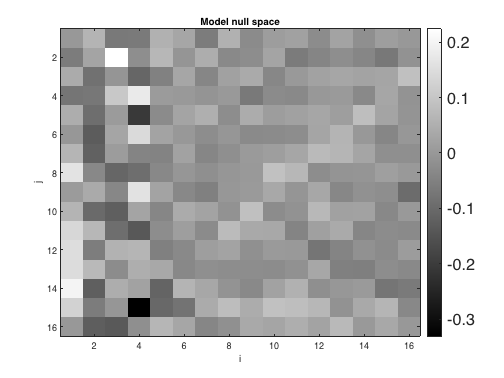

figure(2)
clf
colormap('gray')
imagesc(reshape(V(:,p+1),16,16))
set(colorbar,'Fontsize',18);

xlabel('i'); ylabel('j')
title('Model null space')

### ii. Contour or otherwise display a nonzero model that fits the trivial data set exactly

Any vector in the $V_{i}$ in the model null space satisfies the equation $GV_{i} = 0$ hence we can form a model $m_{o}$ where $$m_o = \sum\limits_{i=p+1}^n \alpha_{i} V_{:,i}$$. We have some many vectors in the model null space so we can pick the first two and set $\alpha=0$ for the rest.

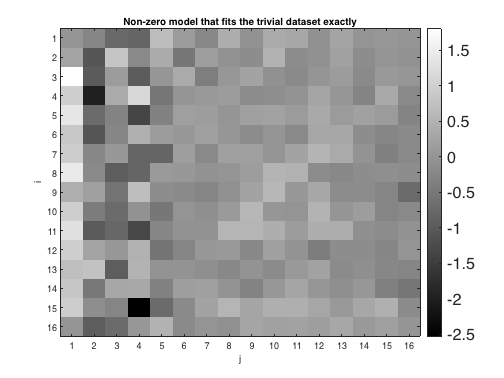

m_o = 6*V(:,p+1) + 5*V(:,p+2);

mm = reshape(m_o,16,16);

figure(3)
clf
colormap('gray')
imagesc(mm)
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16]);
set(gca,'ytick',[1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16]);
xlabel('j')
ylabel('i')
title('Non-zero model that fits the trivial dataset exactly')

### iii. Show the model resolution by contouring or otherwise displaying the 256 diagonal elements of the model resolution matrix, reshaped into an appropriate 16 by 16 grid. Note if there are any model parameters that have perfect resolution.

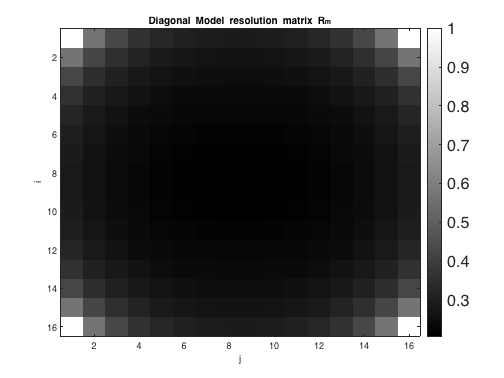

% model resolution matrix
Vp=V(:,1:p);
Rm=Vp*Vp';

Rm = reshape(diag(Rm),16,16);

figure(4)
clf
colormap('gray')

imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Diagonal Model resolution matrix R_{m}')

The model parameters corresponding to the four edges (m_1, m_16, m_241, and m_256) have perfect resolutions.

### (c) Produce a 16 by 16 element contour or other plot of your slowness perturbation model, displaying the maximum and minimum slowness perturbations in the title of the plot. Interpret any internal structures geometrically and in terms of seismic velocity (in m/s). 

The row and diagonal scan solution in the figure below, depicts that there is low slowness(high velocity) along the diagonal, this anomaly is around $-8.9 x 10^{-5}$ s/m, inthat incoporating the background velocity  of $3000$ m/s, yeilds a velocity approximately $$\left(\frac{1}{3000} - 8.9 x 10^{-5}\right) \approx$ $2.44 x 10^{-4}$ = $4092$m/s. However the rowscans aren't well depicted due to limited resolution.

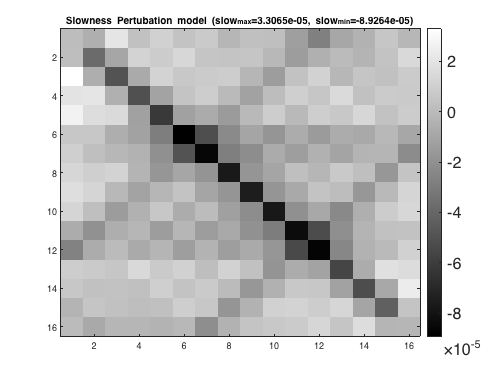

md = reshape(mdagger,16,16);


max_md = max(max(md));
min_md = min(min(md));

figure(5)
clf
colormap('gray')
imagesc(md)
set(colorbar,'Fontsize',18);

title(['Slowness Pertubation model (slow_{max}=',num2str(max_md),', slow_{min}=',num2str(min_md),')'])

### In addition, produce a plot of the data fit and discuss it.

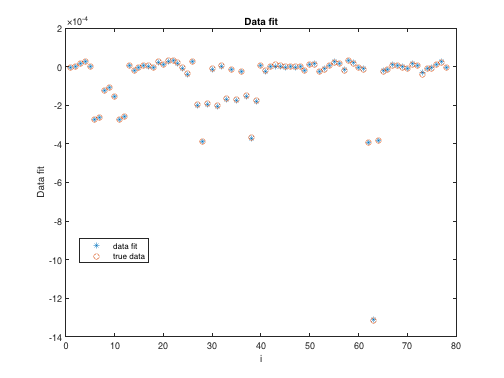

data = G*mdagger;

figure(6)
plot(data,'*'); hold on
plot(t,'o');
xlabel('i'); ylabel('Data fit')
title('Data fit')
legend('data fit','true data',Location='best')

### Comment

According to the plot, the estimated data almost fits the true data.

### (d) Describe how one could use solutions to Gm = d = 0 to demonstrate that very rough models exist that will fit any data set just as well as a generalized inverse model.

A wild model can be generated by superimpossing scaled basis vectors from the model null space onto the generalized inverse solution. We used 50 times the first basis vector from the model nullspace to add to $m_{\dagger}$ to obtain a model in the figure below. 

###  Show one such wild model.

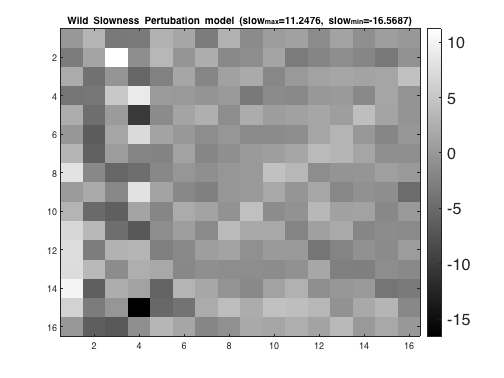

mw = md + 50*reshape(V(:,p+1),16,16);

max_ms = max(max(mw));
min_ms = min(min(mw));

figure(9)
clf
colormap('gray')
imagesc(mw)
set(colorbar,'Fontsize',18);

title(['Wild Slowness Pertubation model (slow_{max}=',num2str(max_ms),', slow_{min}=',num2str(min_ms),')'])

### (e) Plot and interpret the correlation matrix.

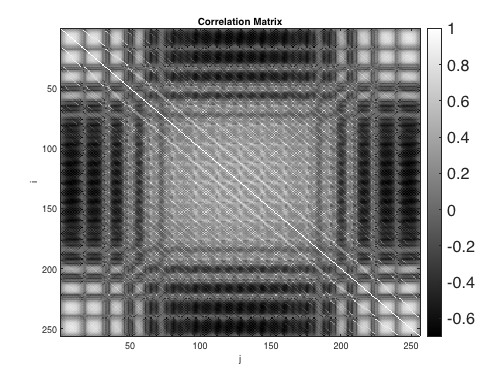

Si = diag(S);
C = 0;
for i=1:p
    C = C + V(:,i)*V(:,i)'/Si(i)^2;
end
C = (std^2)*C;

Corr = corrcoef(C);

figure(7)
clf
colormap('gray')

imagesc(Corr)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Correlation Matrix')

The plot shows how the parameter estimates correlate with each other. The diagonal elements shows how an estimate correlate with itself and as expected, we have perfect correlation along the diagonal. Also, the 4 edges show that the estimates in the edg have high correlation with each other 

### (f) Quantify and discuss stability of slowness perturbation estimates.

CondGd = Si(1)/Si(p)

CondGd = 6.7064

Since the condition number ($$6.7064$$) is small, then the estimates are stable and a small change in the data, will not result in a large change in the estimate.

CondG = Si(1)/Si(78)

CondG = 9.5704e+15

The condition value of G is almost infinite. This means that small changes in the data may result in large changes in our parameter estimates. 